# EXERCISE #1 : Build the Simplest WLAN Network

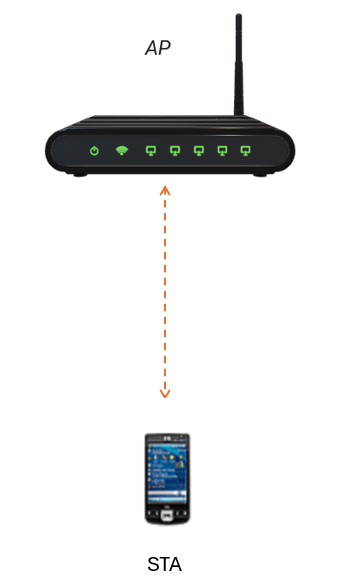

WLAN Network with one AP and one STA 

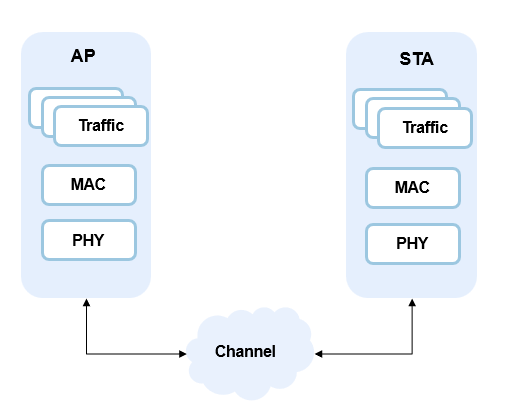

Modeled Blocks 

#### In this exercise, You will learn how to  

- Model a simple WLAN network and explore the WLAN network modeling workflow. 

- Model the physical (PHY), MAC, and application layers for WLAN nodes, along with the wireless channel. 

- Visualize WLAN and Bluetooth data link layer state transitions, capture statistics, and measure network KPIs. 

- Analyze and evaluate WLAN network performance under Bluetooth interference.

- Perform cleanup by closing previously opened windows and figures. 

clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs); 

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

rng(1,"twister");
TU              = 1024e-6; % Time Unit(TU) in WLAN is 1024 us 
simulationTime  = 100*TU;  % Simulation time is set to 100*TU 
networkSimulator = wirelessNetworkSimulator.init;
networkViewerObj = wirelessNetworkViewer(CanvasSize=[50 50 0]);

# Task #1/4 Configure a WLAN Access Point (AP)

**Description of the task**

Configure WLAN AP

- Operates in the 2.4 GHz band with 20 MHz channel bandwidth (Channel 7) 

- Transmits a beacon every 10 TU (10.24 ms) 

- Frame aggregation is disabled by default

**Instructions to complete the task**

Use wlanDeviceConfig() function to configure the AP

Write configuration in a variable named "APCfg"

Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

-     "Mode","AP"

-     "TransmissionFormat", transmissionFormat

-     "BandAndChannel",[band, channel]

-     "ChannelBandwidth",bandwidth

-     "AggregateHTMPDU",enableAggregation

-      "BeaconInterval", 10

transmissionFormat = "HT-Mixed";
band        = 2.4;
channel     = 7;
bandwidth   = 20e6;
enableAggregation = false;

% <enter code below>
APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat", transmissionFormat, ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "AggregateHTMPDU",enableAggregation, ...
    "BeaconInterval", 10);

# Task #2/4 Create a WLAN Access Point (AP)

**Description of the task**

Configure the abstraction level of the MAC and PHY, and set the position of the access point.

**PHY Options**

- **Full PHY (IQ samples)**

- Supports waveform generation and decoding 

- **Abstracted PHY**

- Uses PER tables based on the 802.11ax evaluation methodology 

- Enables PHY abstraction for system-level simulation 

- **Pass-through PHY (MAC calibration)**

- No PHY is modeled 

- Interfered packets are dropped 

**MAC Options**

- **Full MAC**

- EDCA MAC with full MAC frame generation 

- **Abstracted MAC**

- EDCA MAC without MAC frame generation 

**Note / Implication**

- Use **Full MAC** if you want to capture WLAN packets in PCAP files and analyze them in Wireshark.

- All nodes on the network must have same MAC and PHY abstraction

- You can't set Abstracted MAC and full PHY

**Instructions to complete the task**

Use wlanNode() function to instantiate the AP using the configuration you have just created

Hint: Type "doc wlanNode" in the MATLAB Command Window, and see the "Syntax" section.

Name the variable "AP"

Note : use the following values to start with

- "DeviceConfig",APCfg

- "Position", AP_pos

- "PHYAbstractionMethod",phyabstraction

- "MACFrameAbstraction",macabstraction

- Name="AP"

### [Help on creating WLAN node ](https://www.mathworks.com/help/wlan/ref/wlannode.html)

macabstraction = false
phyabstraction = "none";
AP_pos= [0, 0, 0];

% <enter code below>
AP = wlanNode(...
    "Name","AP",...
    "Position",AP_pos, ...
    "DeviceConfig",APCfg,...    
    "MACFrameAbstraction",macabstraction,...
    "PHYAbstractionMethod",phyabstraction); 

#### Visualize the Access Point in the Network Viewer 

Add node to the network viewer for visualization 

addNodes(networkViewerObj,AP,Type="AP");

# Task 3 Configure a WLAN Station (STA)

**Description of the task**

Configure WLAN STA

- Operates in the 2.4 GHz band with 20 MHz channel bandwidth (Channel 7) 

- Frame aggregation is disabled by default

**Instructions to complete the task**

Use wlanDeviceConfig() function to configure the STA

Write configuration in a variable named "STACfg"

Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- "Mode","STA"

-  "TransmissionFormat",transmissionFormat

-  "BandAndChannel",[band, channel]

-  "ChannelBandwidth",bandwidth

-  "AggregateHTMPDU",enableAggregation

% <enter code below>
STACfg = wlanDeviceConfig("Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,... 
    "AggregateHTMPDU",enableAggregation);

# Task 4 Create a WLAN Station (STA)

**Instructions to complete the task**

Use wlanNode() function to instantiate the AP using the configuration you have just created

Hint: Type "doc wlanNode" in the MATLAB Command Window, and see the "Syntax" section.

Name the variable "STA"

Note : use the following values to start with

- "Name","STA"

- "Position",STA_pos

- "DeviceConfig",STACfg    

- "MACFrameAbstraction",macabstraction

- "PHYAbstractionMethod",phyabstraction

STA_pos= [5, 0, 0];

% <enter code below>
STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACFrameAbstraction",macabstraction,...
    "PHYAbstractionMethod",phyabstraction);

#### Visualize the station in the Network Viewer 

Add node to the network viewer for visualization 

addNodes(networkViewerObj,STA,Type="STA");

# Task #3/4 Associate AP with STA

### Define traffic type

- Beacon Only (default)

- Bidirectional

- DL

- UL 

fullBufferTrafficType = "DL"

`Note`` : `

- `As of now, Full buffer configuration generates traffic in AC0.`

- `As full buffer configuration generates AC0(Best Effort) traffic, you can still instantiate traffic of other ACs (AC1(Background), AC2(Video), AC3(`Voice`))  `

- `Traffic generation is implementation dependent and not part of EDCA and QoS. EDCA and QoS define how the generated traffic is differentiated, prioritized, and queued. `

- `Full buffer just represents a traffic pattern where a node always has data to send at any point of time. This pattern can be applied for any Access Category, but we support it for only AC0 in our simulation.`

% Use associateStations() function to define associations between AP's and STA's
% Hint: Click the link below and and see the "Syntax" section.

### [Help on Associating Station ](https://www.mathworks.com/help/wlan/ref/wlannode.associatestations.html)

% AssociateStations is a method of the wlanNode object
% Use first argument as AP
% Use 2nd argument as STA
% Note : please use "FullBufferTraffic" = trafficType in the function call

associateStations(AP,STA,"FullBufferTraffic",fullBufferTrafficType);

PeriodicTrafficType = "off"
if strcmp(PeriodicTrafficType, "on") && strcmp(fullBufferTrafficType, "off")
    ap2staTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=350,PacketSize=200);
    addTrafficSource(AP,ap2staTraffic,DestinationNode=STA);

    sta2apTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=350,PacketSize=200);
    addTrafficSource(STA,sta2apTraffic,DestinationNode=AP);
    plotTrafficPattern(simulationTime,ap2staTraffic)
end

#### **Add nodes to the network **

wlanNodes = [AP, STA];
addNodes(networkSimulator,wlanNodes)
nodes = networkSimulator.Nodes;

**Enable PCAP capture**

enablePCAPCapture = true;
if enablePCAPCapture
    capturePacketsObj =wlanPCAPWriter(Node=wlanNodes);
end

#### Enable capture of IQ samples

enableIQCapture  = true;
if enableIQCapture
    iqSampleObj = wirelessIQLogger(wlanNodes);
end

#### Add channel model to the simulator

channelModel = "TGAX";
if strcmp(channelModel,"TGAX")
    channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
    addChannelModel(networkSimulator,channelFunction(channel));
end

#### Enable packet visualization

enablePacketVisualization = true; 
if enablePacketVisualization
    viewerObj = wirelessTrafficViewer;
    addNodes(viewerObj,nodes);
end

#### Run the simulation

- WirelessNetworkSimulator is an event-driven simulator

- use the run() method to start the simulation

% Create node performance visualization object
perfViewerObj = helperPerformanceViewer(wlanNodes,simulationTime);
run (networkSimulator,simulationTime)

# Task #4/4 Display Statistics at AP

% Use statistics() function to get statistics (APP, MAC, PHY) for AP and STA
% Create a variable names APStatistics 
% Hint:  click the link below see the "Syntax" section.

### [Help on statistics](https://www.mathworks.com/help/wlan/ref/wlannode.statistics.html)

% <enter code below>
APStatistics = statistics(AP,"all")

#### APP layer statistics

APStatistics.App

#### MAC layer Statistics

APStatistics.MAC

#### PHY layer Statistics

APStatistics.PHY

#### Explore statistics at the STA

STAStatistics = statistics(STA);
STAStatistics.PHY
STAStatistics.MAC
STAStatistics.App

#### Calculate throughput, packet loss ratio,latency at nodes 

% Calculate throughput (Mbps) at Nodes
throughputs = throughput(perfViewerObj,[wlanNodes(:).ID])
% Calculate packet loss ratio at Nodes
packetLossRatio = packetLossRatio(perfViewerObj,[wlanNodes(:).ID])
% Calculate Latency (Seconds) at Nodes
averageReceiveLatency = averageReceiveLatency(perfViewerObj,[wlanNodes(:).ID])

if enablePCAPCapture
    delete(capturePacketsObj);
end

#### IQ sample visualization


if enableIQCapture
    fileName = iqSampleObj(1).FileName;
    iqData = load(fileName);
    signalAnalyzer(iqData.Waveform,SampleRate=iqData.Fs);
end

Copyright 2025-2026 The MathWorks, Inc